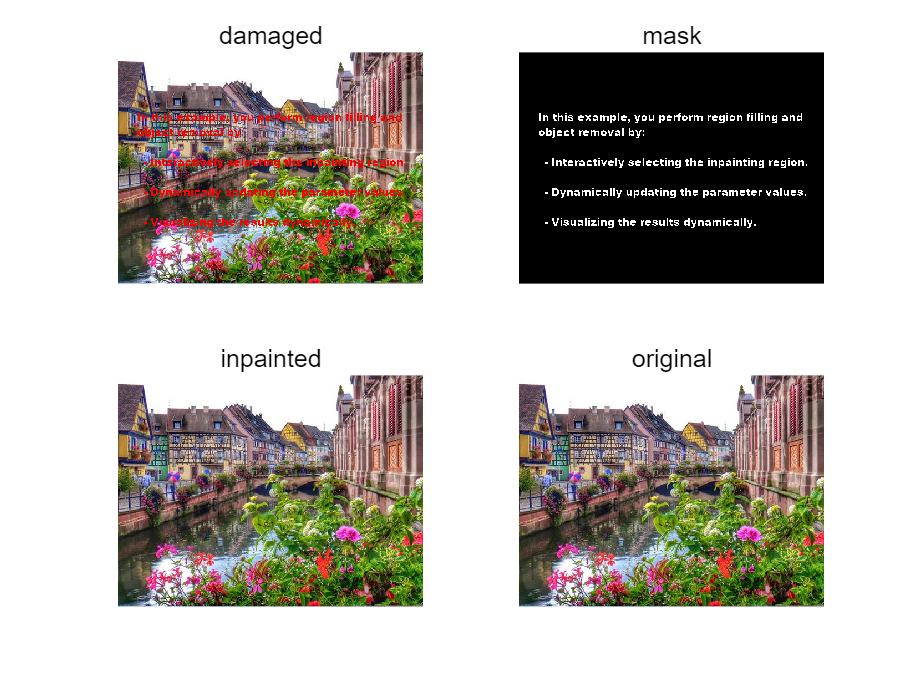

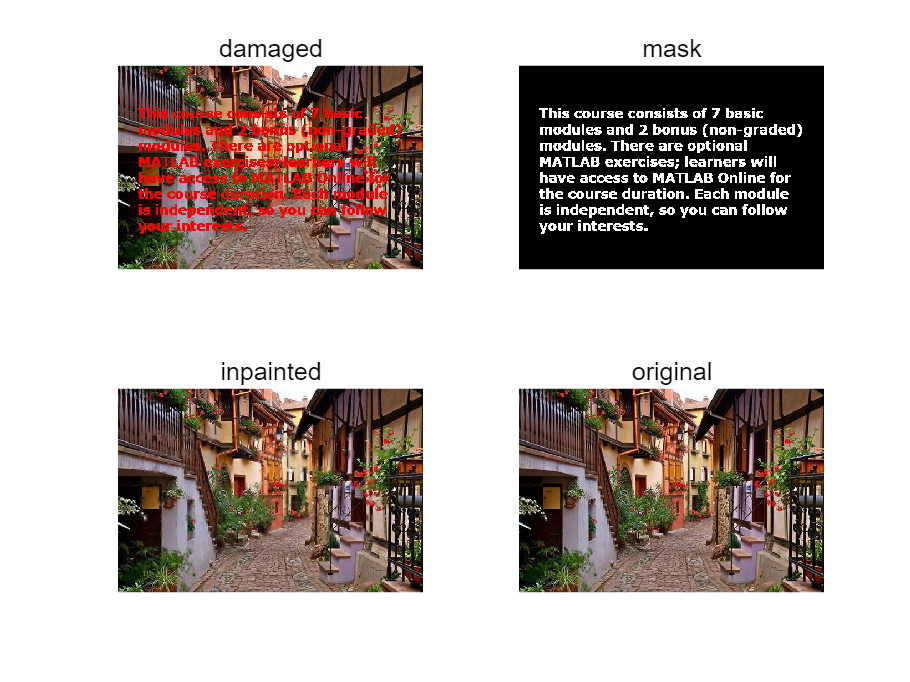

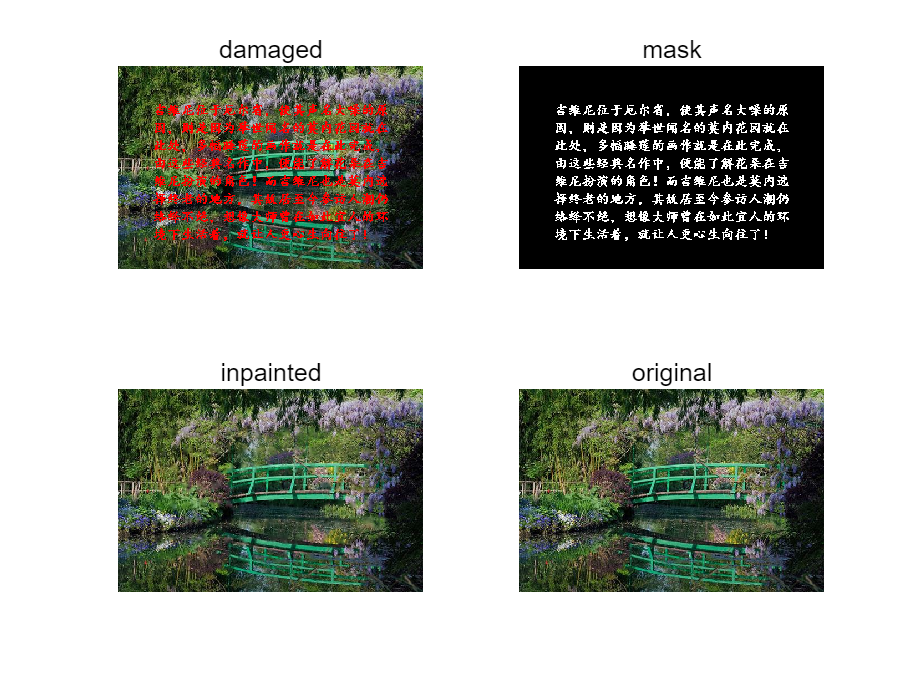

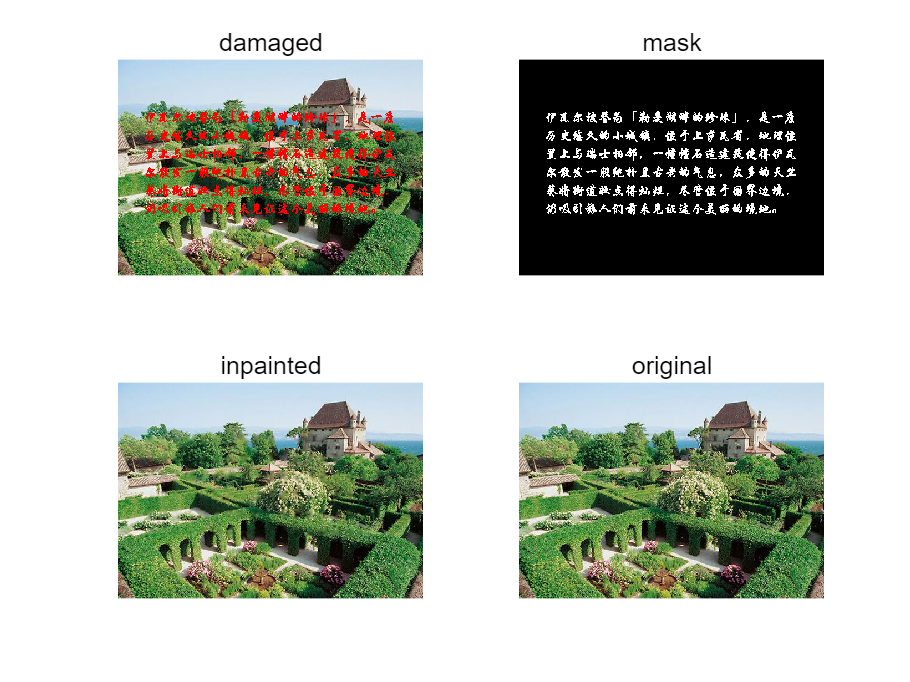

img_list = ["Colmar", "Eguisheim", "Giverny", "Yvoire"]; % names list of 4 pair of images
target_red = [255,0,0]; % mask: all the damaging text are pure red([255, 0, 0]), only the target_red region needed to be inpainted
psnr_values = zeros(length(img_list), 1); % PSNR value
ssim_values = zeros(length(img_list), 1); % SSIM value
for i = 1:length(img_list) % for each pair
    name = img_list(i); % get the img name
    name_damaged = strcat(name, '_damaged.png'); % get the damaged img name
    name_original = strcat(name, '.jpg'); % get the original img name
    img_damaged = imread(name_damaged); % read the damaged img
    img_original = imread(name_original); % read the original img
    mask = img_damaged(:,:,1)==target_red(1) & img_damaged(:,:,2)==target_red(2) & img_damaged(:,:,3)==target_red(3); % build the mask: region where RGB == [255, 0, 0]
    img_inpaint = img_damaged; % first the inpaint result was valued by the damaged img
    for c = 1:3 % for 3 channel(r, g, b)
        img_inpaint(:,:,c) = regionfill(img_damaged(:,:,c), mask); % inpaint the pure red region by calling regionfill
        % img_inpaint(:,:,c) = inpaintExemplar(img_damaged(:,:,c), mask);
    end
    imwrite(img_inpaint, strcat(name, '_inpainted.jpg'), 'Quality', 100); % save the result
    imwrite(mask, strcat(name, '_mask.jpg'), 'Quality', 100); % save the mask
    psnr_values(i) = psnr(img_inpaint, img_original); % calculate PSNR
    ssim_values(i) = ssim(img_inpaint, img_original); % calculate SSIM
    figure; % draw the comparision figure
    subplot(2,2,1); imshow(img_damaged); title('damaged');
    subplot(2,2,2); imshow(mask); title('mask');
    subplot(2,2,3); imshow(img_inpaint); title('inpainted');
    subplot(2,2,4); imshow(img_original); title('original');
end


disp('===== PSNR =====');

===== PSNR =====


for i = 1:length(psnr_values)
    fprintf('%s: %.2f dB\n', img_list(i), psnr_values(i));
end

Colmar: 32.51 dB
Eguisheim: 27.44 dB
Giverny: 29.31 dB
Yvoire: 29.50 dB



disp('===== SSIM =====');

===== SSIM =====


for i = 1:length(ssim_values)
    fprintf('%s: %.2f \n', img_list(i), ssim_values(i));
end

Colmar: 0.99 
Eguisheim: 0.96 
Giverny: 0.96 
Yvoire: 0.97 
